# Lesson 8

Written by Guy Bar Yosef

## Objective

After this class, you should be able to:

- Know how to sample from various probability distributions

- Understand how to simulate state space systems

- Know how to plot bode plots 

# Random Variables

Like many other modern langauges, MATLAB has a toolbox that can give samples from different random variable distributions:

a = rand(1, 5);        % uniform distribution
b = randn(1, 5);       % normal distribution
c = 3 + randn(1).*0.2; % gaussian distrubtion with mean 3 and standard deviation 0.2

You can also call *random* and specify one of many distributions. Check out the documentation for a complete list: https://www.mathworks.com/help/stats/prob.normaldistribution.random.html?s_tid=doc_ta

# State Space Definitions

For those taking Signals, you may already be familiar with the discrete-time state space equations:


$$x[k+1] = Ax[k] + Bu[k] \\
\ y[k] \ \  = Cx[k] + Du[k]$$


where *u* is the input vector to the system, *x *is the system's state variable vector, and* y *is the output vector.

This sort of representation allows us to not only get an output for a system but also keep track of its internal behavior as well. The internal behavior is tracked using state variables. This representation also turns out to be a convenient way to model systems with multiple inputs and outputs. 

Note that if all the eigenvalues of A are less than 1, then we will have both BIBO stability (bounded input, bounded output) and asymptotic stability (state variables and outputs approach 0 as time goes to infinity).

## State Space Setup

% a ss system with 3 state variables and 2 inputs and 4 outputs
A = 0.99*eye(3) + 0.01*randn(3);
abs(eig(A)) % what can we expect from the state variables and outputs?

ans =     0.9964
    0.9855
    0.9855


B = [1/4 1/4 ;
     1/4 1/2 ;
     0   1/4 ];
 
C = [1 -1  1 ;
     0  1  0 ;
     0 -1  0 ;
     1  0 -1 ];
 
D = 0*1*eye(4,2);

## Simulating State Space

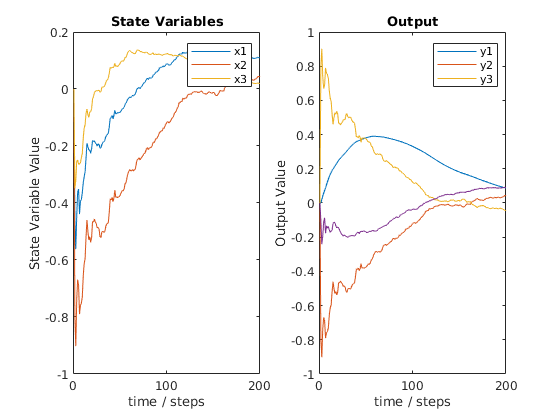

total_steps = 2e2;
X = zeros(3, total_steps+1);
Y = zeros(4, total_steps);

x = zeros(3,1); % note the 0 initial condition
for k = 1:total_steps
    % Current input
    u = randn(2,1)/k; 
    
    % State Space equations
    y = C*x + D*u; % calculate y before updating x
    x = A*x + B*u;
    
    % Store each step's values
    X(:,k+1) = x;
    Y(:,k) = y;
end

figure
subplot(1,2,1)
plot(X')
legend('x1','x2','x3')
title('State Variables'), xlabel('time / steps'), ylabel('State Variable Value')

subplot(1,2,2)
plot(Y')
legend('y1', 'y2', 'y3')
title('Output'), xlabel('time / steps'), ylabel('Output Value')

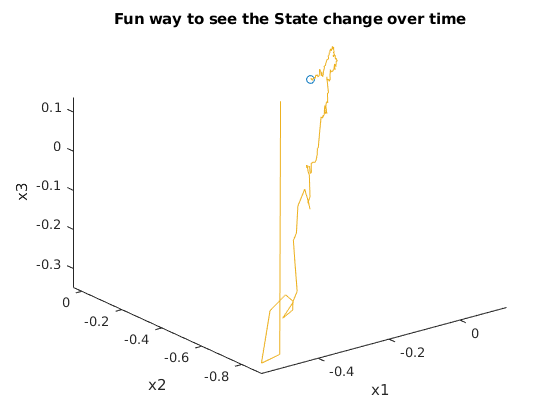

% another fun way to look at the values
figure
comet3(X(1,:)',X(2,:)',X(3,:)')
title('Fun way to see the State change over time')
xlabel('x1'), ylabel('x2'), zlabel('x3');

## Transfer Function

Given a state space representation {A,B,C,D}, the transfer function matrix of the system is:


$$H(z) = C(zI-A)^{-1}B+D$$


assuming 0 initial conditions. The reason we look at the eigenvalues of A when speaking about stability for the system is that every pole in every element of H(z) must be an eigenvalue of A (keep in mind that there can be eigenvalues of A which are not poles). Let's see this for ourselves:

syms z
H_z = C*(z*eye(3) - A)^(-1)*B + D;
single(real(poles(H_z(1,1))))

ans = 3×1 single column vector
    0.9964
    0.9854
    0.9854


single(real(poles(H_z(1,2))))

ans = 3×1 single column vector
    0.9964
    0.9854
    0.9854


## Bode Plots

Bode plots are graphs of the frequency response of a system, with seperate plots for magnitude and phase and log-scaled frequency along the x-axis.

Taking the transfer function at $H(z)_{1,1}$ as an example, first we need to extract it into a valid transfer function form so that we can get the frequency response:

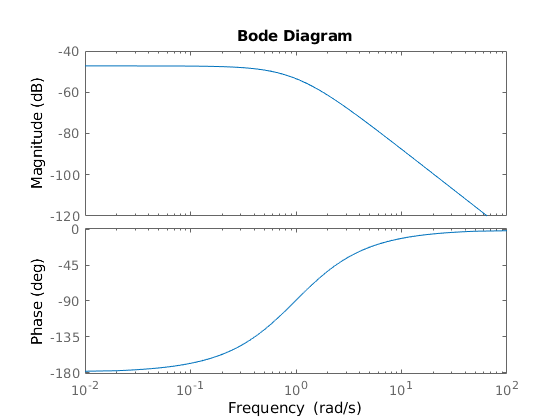

[num, den] = numden(H_z(1,1));
b = sym2poly(num); % get the coefficients of a symbolic polynomial
a = sym2poly(den);

bode(tf(b,a))